# Feature Based Panoramic Image Stitching - MURAL

## Step 1 - Load Images

The image set used in this example contains pictures of a building. These were taken with an uncalibrated smart phone camera by sweeping the camera from left to right along the horizon, capturing all parts of the building.

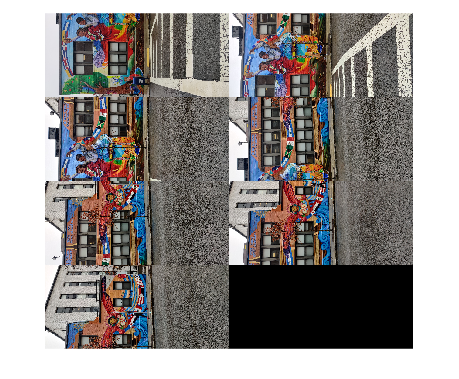

% Load images.
clc
clear all

MuralDir = fullfile("../DataSet", "Mural");
% MuralDir = fullfile(toolboxdir('vision'),'visiondata','building');
MuralScene = imageDatastore(MuralDir);

montage(MuralScene.Files)

% subplots
bins = 256

bins = 256

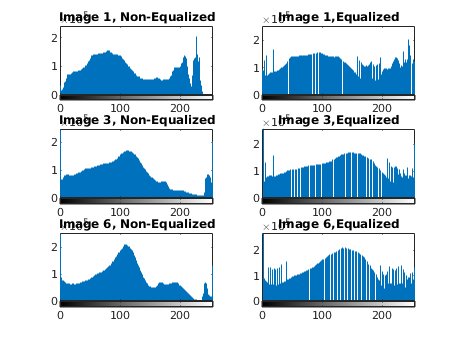

close all
figure
subplot(3,2,1)
imhist(readimage(MuralScene,1),bins)
title("Image 1, Non-Equalized")
subplot(3,2,2)
imhist(histeq(readimage(MuralScene,1),bins),bins)
title("Image 1,Equalized")
subplot(3,2,3)
imhist(readimage(MuralScene,3),bins)
title("Image 3, Non-Equalized")
subplot(3,2,4)
imhist(histeq(readimage(MuralScene,3),bins),bins)
title("Image 3,Equalized")
subplot(3,2,5)
imhist(readimage(MuralScene,6),bins)
title("Image 6, Non-Equalized")
subplot(3,2,6)
imhist(histeq(readimage(MuralScene,6),bins),bins)
title("Image 6,Equalized")

## Step 2 - Register Image Pairs

To create the panorama, start by registering successive image pairs using the following procedure:

- Detect and match features between $I(n)$ and $I(n-1)$.

- Estimate the geometric transformation, $T(n)$, that maps $I(n)$ to $I(n-1)$.

- Compute the transformation that maps $I(n)$ into the panorama image as $T(n) * T(n-1) * ... * T(1)$.

close all

tileSize = [4,4];
numPoints  = 10000;
scale = 0.3

scale = 0.3000

rot   = -90

rot = -90

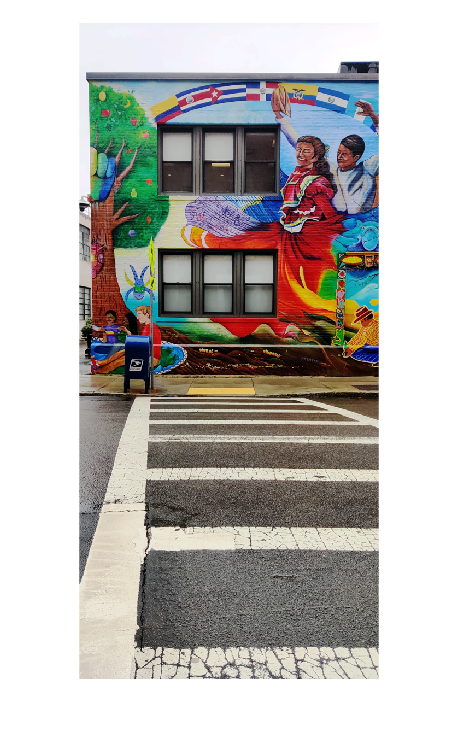



I = histeq(readimage(MuralScene,1));
I = imresize(I, scale);
% Initialize features for I(1)
I = imrotate(I, rot);
imshow(I)


grayImage = im2gray(I);
numImages = numel(MuralScene.Files);
tforms(numImages) = projective2d(eye(3));

% Initialize variable to hold image sizes.
imageSize = zeros(numImages,2);


 [y,x,m] = harris(grayImage,numPoints,'tile',tileSize,'hsize',3,'sigma',0.5);

 corner_points = cornerPoints([y,x],"Metric",m)

corner_points =   10000×1 cornerPoints array with properties:

    Location: [10000×2 single]
      Metric: [10000×1 single]
       Count: 10000

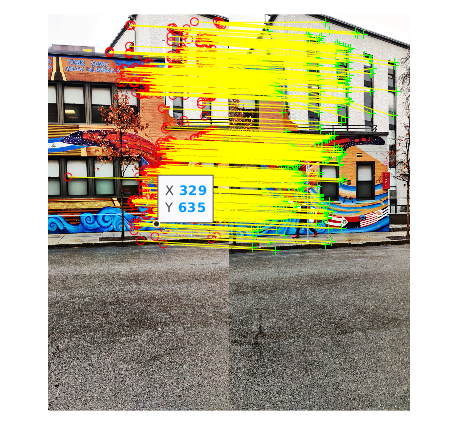

%  corner_points =detectHarrisFeatures(grayImage);

 [features, points] = extractFeatures(grayImage, corner_points);
 
 
% Iterate over remaining image pairs
for n = 2:numImages
    I_old = I;
    % Store points and features for I(n-1).
    pointsPrevious = points;
    featuresPrevious = features;
        
    % Read I(n).
    I = histeq(readimage(MuralScene, n));
    I = imresize(I,scale);
    I = imrotate(I, rot);    
    % Convert image to grayscale.
    grayImage = im2gray(I);    
    
    % Save image size.
    imageSize(n,:) = size(grayImage);
    
    % Detect and extract Harris Corner features for I(n).
 [y,x,m] = harris(grayImage,numPoints,'tile',tileSize,'hsize',3,'sigma',0.5);
    corner_points = cornerPoints([x,y], "Metric",m);
    [features, points] = extractFeatures(grayImage, corner_points);
  
    % Find correspondences between I(n) and I(n-1).
    indexPairs = matchFeatures(features, featuresPrevious);
       
    matchedPoints = points(indexPairs(:,1), :);
    matchedPointsPrev = pointsPrevious(indexPairs(:,2), :);        
    showMatchedFeatures(I_old, I, matchedPointsPrev, matchedPoints,'montage');

    % Estimate the transformation between I(n) and I(n-1).
    tforms(n) = estimateGeometricTransform2D(matchedPoints, matchedPointsPrev,...
        'projective', 'Confidence', 99.9, 'MaxNumTrials', 5000);
    
    % Compute T(n) * T(n-1) * ... * T(1)
    tforms(n).T = tforms(n).T * tforms(n-1).T; 
end

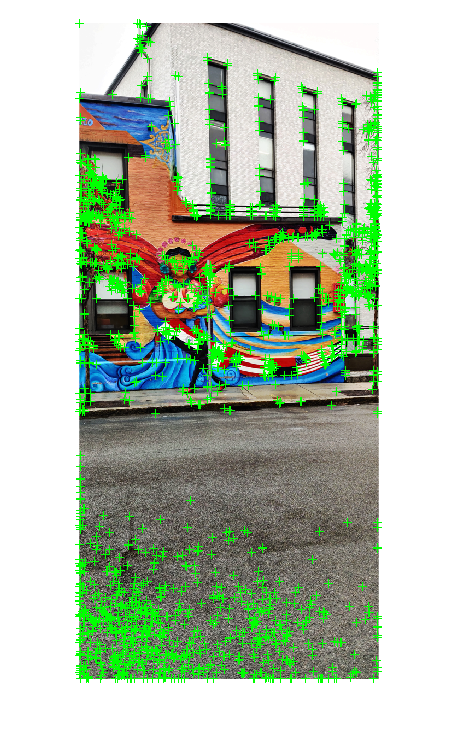


figure
strongest = selectStrongest(corner_points,2000);

 imshow(I)
 hold on
 plot(strongest)
 hold off

At this point, all the transformations in `tforms` are relative to the first image. This was a convenient way to code the image registration procedure because it allowed sequential processing of all the images. However, using the first image as the start of the panorama does not produce the most aesthetically pleasing panorama because it tends to distort most of the images that form the panorama. A nicer panorama can be created by modifying the transformations such that the center of the scene is the least distorted. This is accomplished by inverting the transform for the center image and applying that transform to all the others.

Start by using the `projective2d` `outputLimits` method to find the output limits for each transform. The output limits are then used to automatically find the image that is roughly in the center of the scene.

% Compute the output limits for each transform.
for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);    
end

Next, compute the average X limits for each transforms and find the image that is in the center. Only the X limits are used here because the scene is known to be horizontal. If another set of images are used, both the X and Y limits may need to be used to find the center image.

avgXLim = mean(xlim, 2);
[~,idx] = sort(avgXLim);
centerIdx = floor((numel(tforms)+1)/2);
centerImageIdx = idx(centerIdx);

Finally, apply the center image's inverse transform to all the others.

Tinv = invert(tforms(centerImageIdx));
for i = 1:numel(tforms)    
    tforms(i).T = tforms(i).T * Tinv.T;
end

## Step 3 - Initialize the Panorama

Now, create an initial, empty, panorama into which all the images are mapped. 

Use the `outputLimits` method to compute the minimum and maximum output limits over all transformations. These values are used to automatically compute the size of the panorama.

for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);
end

maxImageSize = max(imageSize);

% Find the minimum and maximum output limits. 
xMin = min([1; xlim(:)]);
xMax = max([maxImageSize(2); xlim(:)]);

yMin = min([1; ylim(:)]);
yMax = max([maxImageSize(1); ylim(:)]);

% Width and height of panorama.
width  = round(xMax - xMin);
height = round(yMax - yMin);

% Initialize the "empty" panorama.
panorama = zeros([height width 3], 'like', I);

## Step 4 - Create the Panorama

Use `imwarp` to map images into the panorama and use `vision.AlphaBlender` to overlay the images together.

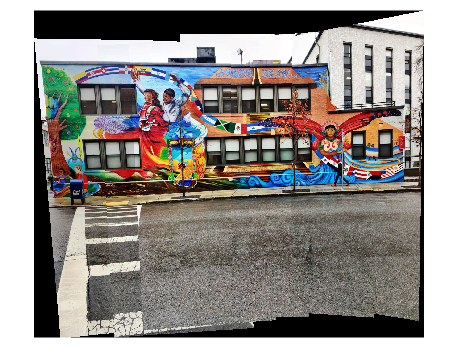

blender = vision.AlphaBlender('Operation', 'Binary mask', ...
    'MaskSource', 'Input port');  

% Create a 2-D spatial reference object defining the size of the panorama.
xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width], xLimits, yLimits);

% Create the panorama.
for i = 1:numImages
    
    I = histeq(readimage(MuralScene, i));  
    I = imresize(I, scale);
    I = imrotate(I, rot);    
   
    % Transform I into the panorama.
    warpedImage = imwarp(I, tforms(i), 'OutputView', panoramaView);
                  
    % Generate a binary mask.    
    mask = imwarp(true(size(I,1),size(I,2)), tforms(i), 'OutputView', panoramaView);
    
    % Overlay the warpedImage onto the panorama.
    panorama = step(blender, panorama, warpedImage, mask);
end

figure
imshow(panorama)

[1] Matthew Brown and David G. Lowe. 2007. Automatic Panoramic Image Stitching using Invariant Features. Int. J. Comput. Vision 74, 1 (August 2007), 59-73.

*Copyright 2014 The MathWorks, Inc.*